Homework 7 

Shaobo Wang

Question 1

clear;clc

The nominal plant is:

s = tf('s');
a = 100;
G = 1/(s^2+a/50*s+a^2)*[s-a^2,a*(s+1);-a*(s+1),s-a^2];

The uncertain model is:

D1 = ultidyn('D1',[1,1]);
D2 = ultidyn('D2',[1,1]);
wI = (20*s+10)/(s+100);
WI = [wI,0;0,wI];
WI_unc = [D1*wI,0;0,D2*wI];
Gp = (eye(2)+WI_unc)*G;

Performance weight:

WP = (0.5*s+20)/(s+0.2)*eye(2,2);

(a) Design controller with mixsyn

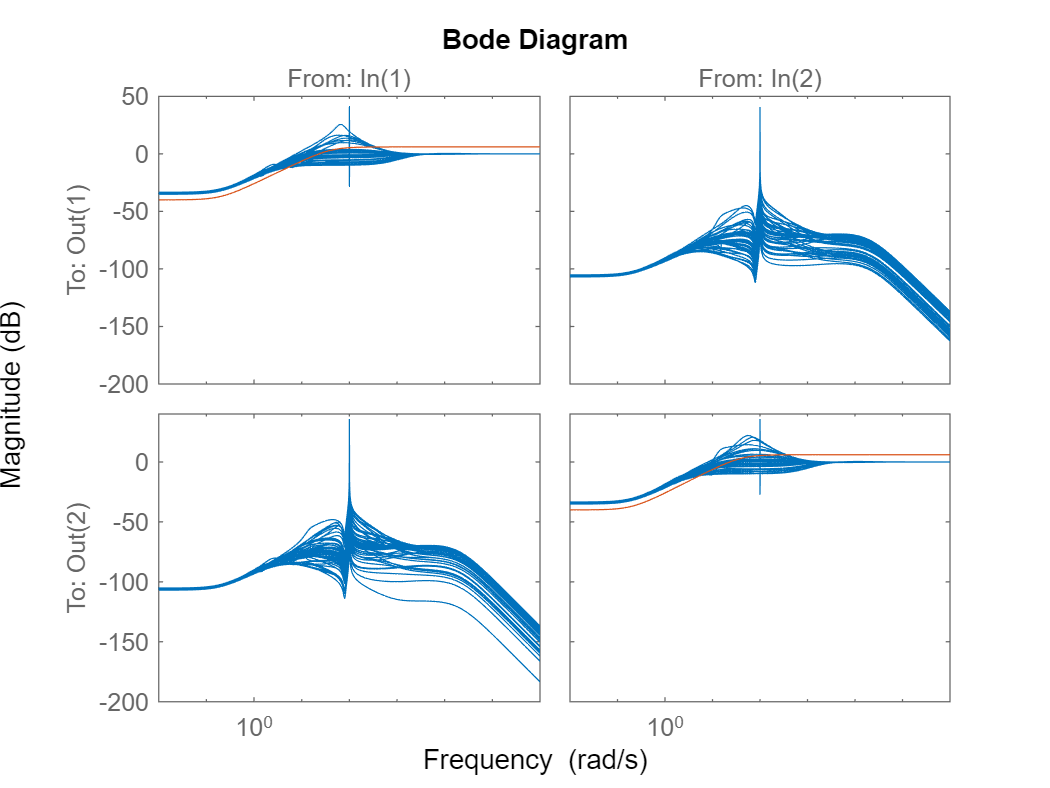

[K_mix,CL_mix,GAM_mix] = mixsyn(Gp,WP,[],WI);  % use unc model
T_mix = feedback(Gp*K_mix,eye(2));
S_mix = eye(2)-T_mix;
S_mix_vec = usample(S_mix,50);
bodemag(S_mix_vec,inv(WP));

Check for RS:

isstable(T_mix.NominalValue)

ans = logical
   1


[stabmarg,~] = robstab(S_mix);
mu_RS = 1/stabmarg.LowerBound

mu_RS = 1.8530

Check for RP:

[perfmarg,~] = robustperf(WP*S_mix);
mu_RP = 1/perfmarg.LowerBound

mu_RP = 2.7291

The system didn't meet RS or RP goals since all mu values are greater than one.

(b) Design with $\mu$ synthesis

Assume negative feedback, find the generalized plant:

systemnames = 'Gp WP';
inputvar = '[r{2};u{2}]';
outputvar = '[WP;r-Gp]';
input_to_Gp = '[u]';
input_to_WP = '[r-Gp]';
cleanupsysic = 'yes';
Pmu = sysic;

Minimize mu:

[K_mu,CLP_mu,mu] = musyn(Pmu,2,2);



D-K ITERATION SUMMARY:
-----------------------------------------------------------------
                       Robust performance               Fit order
-----------------------------------------------------------------
  Iter         K Step       Peak MU       D Fit             D
    1           2.717        2.711        2.734            12
    2           2.589        2.589        2.614            20
    3           2.589        2.588        2.588            20
    4            2.59        2.589        2.592            20

Best achieved robust performance: 2.59



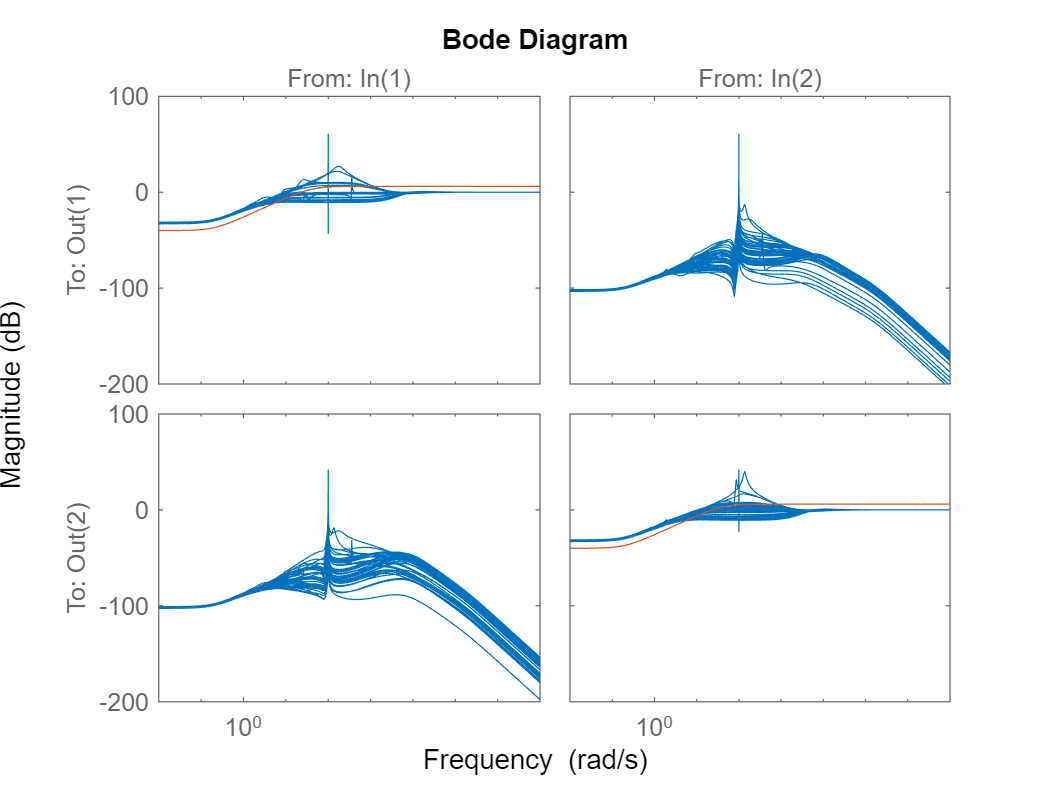

T_mu = feedback(Gp*K_mu,eye(2));
S_mu = eye(2)-T_mu;
S_mu_vec = usample(S_mu,50);
bodemag(S_mu_vec,inv(WP));

Check for RS:

isstable(T_mu.NominalValue)  % NS

ans = logical
   1


[stabmarg,~] = robstab(S_mu);
mu_RS = 1/stabmarg.LowerBound

mu_RS = 2.0993

Check for RP:

[perfmarg,~] = robustperf(WP*S_mu);
mu_RP = 1/perfmarg.LowerBound

mu_RP = 2.5879

The system didn't meet RS or RP goals since all mu values are greater than one.

Compare with hinf-mixsyn:

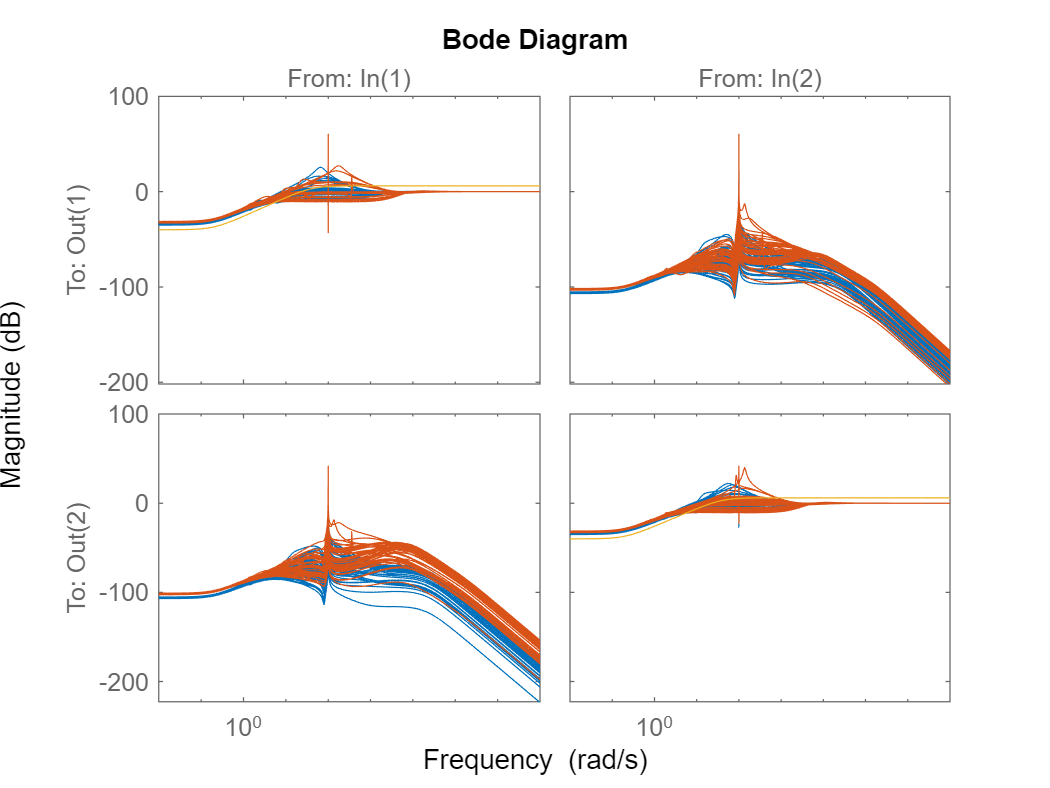

bodemag(S_mix_vec, S_mu_vec, inv(WP))

Question 2

(a) K stabilizes P means it's NS

1. RS:

The generalized plant is:


$$\left[
\matrix{
z\cr v}
\right]=
\left[
\matrix{
0&0&1\cr -PW_1&-W_2&-P}
\right]
\left[
\matrix{
w_1\cr w_2\cr u}
\right]$$


The LFT of this plant is:


$$N=
\left[
\matrix{
0&0}
\right]+
K(1+PK)^{-1}
\left[
\matrix{
-PW_1&-W2}
\right]\\
N=-\left[
\matrix{
W_1T&W_2KS}
\right]$$


According to the small gain theory:


$$\|N\Delta\|_{\infty}=
\|W_1T\Delta_1+W_2KS\Delta_2\|_{\infty}<1$$


Since $\|\Delta_1\|_{\infty}\leq1,
\|\Delta_2\|_{\infty}\leq1$,


$$\||W_1T|+|W_2KS|\|_{\infty}\leq1$$


2. RP:

In this case, Wp=1 according to the diagram, RP is equivalent to $\|W_PS_p\|_{\infty}=\|S_p\|_{\infty}\leq1$.

The disturbance can be seen as another uncertanty.

Use the Nyquist plot as uncertainty disk:


$$|W_3|+|W_1L|+|W_2K|<|1+L| \ \forall \omega$$


Therefore,


$$\|W_3S\|_{\infty}+\|W_1T\|_{\infty}+\|W_2KS\|_{\infty}\leq1$$


(b) The generalized plant is:


$$\left[
\matrix{
z_I\cr z_O\cr v}
\right]=
\left[
\matrix{
0&0&W_{1I}\cr 
W_{1O}GW_{2I}&0&W_{1O}G\cr
-GW_{2I}&-W_{2O}&-G}
\right]
\left[
\matrix{
w_I\cr w_O\cr u}
\right]$$


The LFT of this plant is:


$$M=
\left[
\matrix{
0&0\cr 
W_{1O}GW_{2I}&0}
\right]+
\left[
\matrix{
W_{1I}\cr 
W_{1O}G\cr}
\right]
K(I+GK)^_{-1}
\left[
\matrix{
-GW_{2I}&-W_{2O}}
\right]\\
=
\left[
\matrix{
0&0\cr 
W_{1O}GW_{2I}&0}
\right]+
\left[
\matrix{
-W_{1I}K(I+GK)^_{-1}GW_{2I}&-W_{1I}K(I+GK)^_{-1}W_{2O}\cr 
-W_{1O}GK(I+GK)^_{-1}GW_{2I}&-W_{1O}GK(I+GK)^_{-1}W_{2O}\cr}
\right]\\
= 
\left[
\matrix{
-W_{1I}K(I+GK)^_{-1}GW_{2I}&-W_{1I}K(I+GK)^_{-1}W_{2O}\cr 
W_{1O}GW_{2I}-W_{1O}GK(I+GK)^_{-1}GW_{2I}&-W_{1O}GK(I+GK)^_{-1}W_{2O}\cr}
\right]$$


Assume: 


$$T_I=K(I+GK)^{-1}G,
T=GK(I+GK)^{-1},
S = (I+GK)^{-1}$$


The LFT can be written as:


$$M=
\left[
\matrix{
-W_{1I}T_IW_{2I}&-W_{1I}KSW_{2O}\cr 
W_{1O}(I-T)GW_{2I}&-W_{1O}TW_{2O}\cr}
\right]\\
=\left[
\matrix{
-W_{1I}T_IW_{2I}&-W_{1I}KSW_{2O}\cr 
W_{1O}SGW_{2I}&-W_{1O}TW_{2O}\cr}
\right]\\
=\left[
\matrix{
W_{1I}&0\cr 
0&-W_{1O}0\cr}
\right]
\left[
\matrix{
-T_I&-KS\cr 
SG&-T\cr}
\right]
\left[
\matrix{
W_{2I}&0\cr 
0&W_{2O}\cr}
\right]$$


(c) 

clear;clc

The plant model:

s = tf('s');
G = 1/(75*s+1)*[-87.8,1.4;-108.2,-1.4];
K = 0.7/s/G;
wI = (s+0.2)/(0.5*s+1);
WI = [wI,0;0,wI];
eps = 1e-3;
WP = (s/2+0.05)/(s+eps)*eye(2);

1. diagonal uncertainty:

D1 = ultidyn('D1',[1,1]);
D2 = ultidyn('D2',[1,1]);
D_diag = [D1,0;0,D2];
Gp_diag = G*(eye(2)+D_diag*WI);
S_diag = eye(2)-feedback(Gp_diag*K,eye(2));
[perfmarg_diag,~] = robustperf(WP*S_diag);
mu_diag = 1/perfmarg_diag.LowerBound

mu_diag = 0.9666

2. full-block uncertainty:

D1 = ultidyn('D1',[1,1]);
D2 = ultidyn('D2',[1,1]);
D3 = ultidyn('D3',[1,1]);
D4 = ultidyn('D4',[1,1]);
D_full = [D1,D2;D3,D4];
Gp_full = G*(eye(2)+D_full*WI);
S_full = eye(2)-feedback(Gp_full*K,eye(2));
[perfmarg_full,~] = robustperf(WP*S_full);
mu_full = 1/perfmarg_full.LowerBound

mu_full = 4.6265

Therefore, close-loop system with given controller has RP for diagonal case but not for full-block case.

Question 3

clear;clc

(a) H-inf norm

s = tf('s');
G1 = [1/(s+5),(s-2)/(s+10);10/(s^2+4*s+15),3*s/(4*s+3)];
calNorm_inf(G1)

ans = 1.2505

norm(G1,'inf')

ans = 1.2500

(b) H-2 norm

G2 = [1/(s+5),1/(s+10);10/(s^2+4*s+15),3/(4*s+3)];
calNorm_2(G2)

ans = 1.1655

norm(G2,2)

ans = 1.1655

The results from custom function and matlab function are the same for both H-inf and H-2 norm.

function norm = calNorm_inf(G)
Gss = ss(G);
A = Gss.A;
B = Gss.B;
C = Gss.C;
D = Gss.D;
eps = 1e-6;

gamh = 100;
gaml = 0;
gam_try = gamh;
gam_new = 1/2*(gamh+gaml);
while(abs(gam_new-gam_try)>1e-3)  %Stopping criterion
    gam_try = gam_new;
    R = gam_try^2*eye(size(D,2))-D'*D;
    Ham = [A+B/R*D'*C,B/R*B';-C'*(eye(size(D,1))+D/R*D')*C,-(A+B/R*D'*C)'];
    e = eig(Ham);
    if any(abs(real(e))<eps)
        gaml = gam_try;
    else
        gamh = gam_try;
    end
    gam_new = 1/2*(gamh+gaml);
end
norm = gam_new;
end

function norm = calNorm_2(G)
Gss = ss(G);
B = Gss.B;
Q = gram(Gss,"o");
norm = sqrt(trace(B'*Q*B));
end